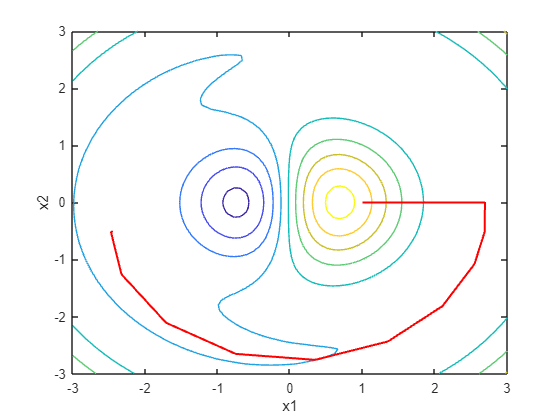

clear all;
close all;
syms x1 x2

eps = 1e-6;
P1=[1, 0]; 
P2=[2, 0];

f(x1, x2) =  0.3*x1+0.1*x2+(-3.5+0.5*x1^2+0.5*x2^2)^2+100*x1* exp(-x1^2 - x2^2);

n_max = 20;
step = 0;
[route, rozwiazanie] = newton(f, eps, P1, n_max);

syms x1 x2
fcontour(f(x1, x2), [-3 3])
hold on
plot(route(:, 1), route(:, 2), 'r', 'linewidth', 1.5)
hold off
xlabel("x1")
ylabel("x2")

disp("Przybliżone minimum = " + num2str(rozwiazanie(1)) + ", " + num2str(rozwiazanie(2)))

Przybliżone minimum = -2.454, -0.50246



[route, rozwiazanie] = newton(f, eps, P2, n_max);

 
Exiting: Maximum number of function evaluations has been exceeded
         - increase MaxFunEvals option.
         Current function value: -1.117118 



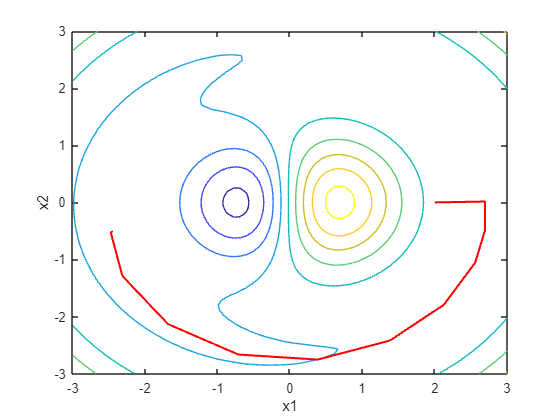


syms x1 x2
fcontour(f(x1, x2), [-3 3])
hold on
plot(route(:, 1), route(:, 2), 'r', 'linewidth', 1.5)
hold off
xlabel("x1")
ylabel("x2")

disp("Przybliżone minimum = " + num2str(rozwiazanie(1)) + ", " + num2str(rozwiazanie(2)))

Przybliżone minimum = -2.454, -0.50246


function [route, result] = newton(f,eps,x0,nmax)
syms x1 x2 lambda
grad = gradient(f);
hess = hessian(f,[x1,x2]);
i = 0;
x = x0;
route = [x0];
while i <= nmax
    gradx = double(grad(x(1), x(2)));
    hessx = double(hess(x(1), x(2)));
    invhessx = inv(hessx);
    kierunek_newtona = -invhessx * gradx;
    h(lambda) = f(x(1)+lambda*kierunek_newtona(1),x(2)+lambda*kierunek_newtona(2));
    l0 = fminsearch(h, 0);
    x_new = x + l0*kierunek_newtona';
    warunek = norm(x_new - x)^2;
    route = [route; x_new];
    if warunek < eps
        result = x_new;
        return
    end
    x = x_new;
    i = i + 1;
end
result = x;
end